# Maximise the MATLAB Peaks Function

## Section 1.0 - Set Up

If the "Random" option is selected from the drop down menu on line 4, then a space-filling design ( Sobol sequence generator) is generated of the size selected in the edit box on line 9 of the code. Alternatively, if the "Fixed" option is selected from the drop down menu, then a constant design is used. In either case, we assume the form of ***f(x)*** is unknown, and iid normally distributed noise with a standaard deviation of 0.2 is added to the data - mimicing the act of sampling by measurement. Thus, even using the "Fixed" design, different results will be generated each time the live script is run.

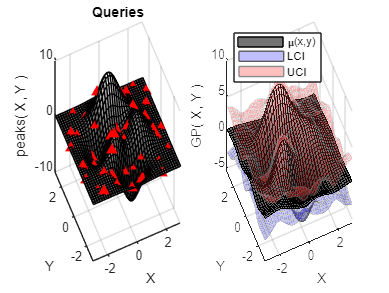

clc
clear
%---------------------------------------------------------------------
% Select the acquisition function
%---------------------------------------------------------------------
AcqFcn = "ucb";
[ X, Y, Z ] = peaks( 40 );
Selection = "Random";
if contains( "Random", Selection )
    %-----------------------------------------------------------------
    % Generate 2-D Sobol sequence - space-filling design
    %-----------------------------------------------------------------
    DesignSize = 45;
    H = sobolset( 2 );
    Hs = scramble( H, "MatousekAffineOwen" );
    D = net( Hs, DesignSize );
    %-----------------------------------------------------------------
    % Map the design to the interval [ -3, 3 ]
    %-----------------------------------------------------------------
    D = [ 6, 6 ] .* ( D ) - [ 3, 3];
else
    %-----------------------------------------------------------------
    % Use fixed data leading to the global maximum
    %-----------------------------------------------------------------
    D = [-2.888	2.182	-1.084	0.197	-1.742	2.541	-0.731	1.338	-2.507	1.802	-1.489	0.601	-2.145	2.946	-0.351	0.957	-2.706	2.000	-0.892	0.004
         -1.253	0.789	2.817	-2.554	0.341	-0.618	-1.591	2.040	1.746	-2.219	-0.168	0.468	-2.661	2.376	1.426	-0.939	1.093	-1.370	-2.343	2.792].';
end
x = D( :, 1 );
y = D( :, 2 );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
Sigma = 0.2;
z = peaks( x, y ) +  Sigma*randn( size(x) );
plot3( x, y, z, 'r^', 'MarkerFacecolor', 'red');
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
title( Ax, "Queries" );
B = bayesOpt( "gpr", AcqFcn );
B = B.setProblemTypeState( "Maximisation" );
%-----------------------------------------------------------------
% Define the data coding: [-3, 3] --> [ -1, 1]
%-----------------------------------------------------------------
B = B.conDataCoding( [-3, -3 ], [ 3, 3 ] );
%-----------------------------------------------------------------
% Set the training data and train the model
%-----------------------------------------------------------------
B = B.setTrainingData( [x, y], z );   
%-----------------------------------------------------------------
% Plot the predictions
%-----------------------------------------------------------------
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

I = 0;

## SECTION 2.0 - Define bayesOpt Object & Perform Algorithm Iteration 1.0

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", B.Xlo, "ub", B.Xhi );

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -5.838206e+00    0.000e+00    2.053e+01
    1      12   -6.457139e+00    0.000e+00    8.408e+00    9.926e-02
    2      18   -6.487091e+00    0.000e+00    1.294e+01    2.050e-02
    3      21   -6.706888e+00    0.000e+00    1.304e+00    3.456e-02
    4      24   -6.708752e+00    0.000e+00    1.000e-01    3.536e-03
    5      27   -6.708829e+00    0.000e+00    2.013e-02    3.746e-04
    6      30   -6.708831e+00    0.000e+00    2.076e-04    8.333e-05
    7      33   -6.708831e+00    0.000e+00    2.001e-06    8.807e-07
    8      36   -6.708831e+00    0.000e+00    2.178e-06    9.696e-09
    9      39   -6.708831e+00    0.000e+00    6.624e-06    1.344e-08
   10      43   -6.708831e+00    0.000e+00    4.299e-06    3.811e-09
   11      51   -6.708831e+00    0.000e+00    2.167e-06    3.847e-09
   12      55   -6.708831e+00    0.000e+00    2

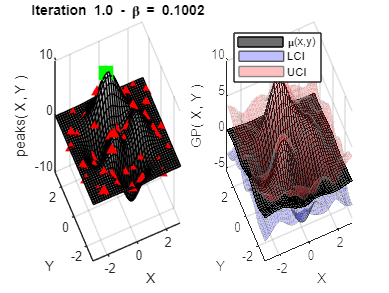

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

## SECTION 3.0 - Subsequent Iterations

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", [ -3, -3], "ub", [ 3, 3 ]);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -7.764922e+00    0.000e+00    1.214e+01
    1      14   -7.849517e+00    0.000e+00    9.324e-01    1.836e-02
    2      24   -7.857583e+00    0.000e+00    5.585e-01    5.849e-03
    3      34   -7.858479e+00    0.000e+00    3.868e-02    1.805e-03
    4      48   -7.858498e+00    0.000e+00    1.588e-02    2.062e-04
    5      61   -7.858498e+00    0.000e+00    6.793e-03    7.031e-05
    6      64   -7.858498e+00    0.000e+00    8.819e-03    2.434e-05
    7      67   -7.858498e+00    0.000e+00    6.752e-03    1.674e-05
    8      70   -7.858498e+00    0.000e+00    4.130e-04    9.433e-06
    9      73   -7.858498e+00    0.000e+00    2.000e-04    7.726e-07
   10      76   -7.858498e+00    0.000e+00    4.000e-05    4.894e-07
   11      79   -7.858498e+00    0.000e+00    2.119e-06    1.159e-07
   12      82   -7.858498e+00    0.000e+00    7

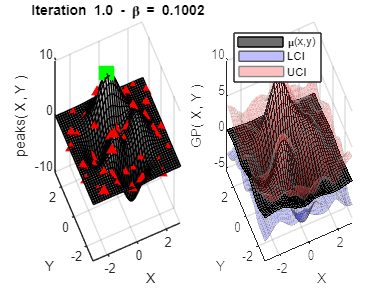

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );

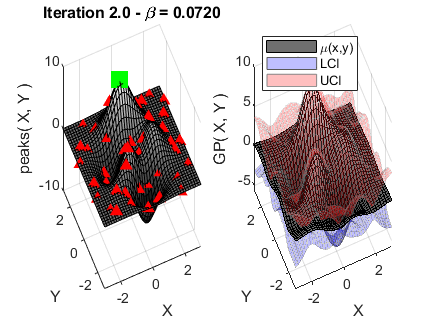

figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );